% Load problem1.mat to have access to variables abd_sig1 and mhb
load("problem1.mat")

% The sampling rates are 1000 Hz
FS = 1000;

% Calculate sample timing vector in seconds starting from 0
t = linspace(0, length(mhb)/FS, length(mhb))

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490



% Estimate c2 from abd_sig1 and mhb using the scalar projection formula
c2_projection = (abd_sig1.' * mhb) / (mhb.' * mhb)

c2_projection = 1.0174


% Estimate c2 from abd_sig1 and mhb using the pseudoinverse function (pinv)
c2_pinv = pinv(mhb)*abd_sig1

c2_pinv = 1.0174


% Estimate c2 from abd_sig1 and mhb using the backslash operator (\)
c2_operator = mhb\abd_sig1

c2_operator = 1.0174


% Calculate the fetal ECG by cancelling out the scaled mother's ECG using projection based estimation coefficient
fetus = abd_sig1 - c2_projection * mhb

fetus =    -0.0178
    0.0098
   -0.0286
   -0.0113
    0.0004
   -0.0146
   -0.0277
    0.0065
   -0.0120
    0.0018


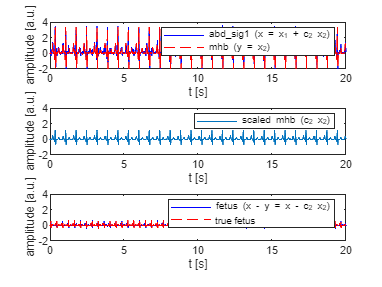


visualize_ecgs(t, abd_sig1, mhb, fetus, fhb, c2)

% Load problem2.mat to have access to variables abd_sig1 and mhb_ahead
load("problem2.mat")

% The sampling rates are 1000 Hz
FS = 1000;

% Calculate sample timing vector in seconds starting from 0
t = linspace(0, length(abd_sig1)/FS, length(abd_sig1))

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490



% Estimate the time lag using cross correlation
% (Calculate cross correlation using the xcorr function and then
% use the max function to find the lag giving maximal correlation)
[r,lags] = xcorr(abd_sig1, mhb_ahead)

r = 1.0e+04 *

   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


lags =       -19999      -19998      -19997      -19996      -19995      -19994      -19993      -19992      -19991      -19990      -19989      -19988      -19987      -19986      -19985      -19984      -19983      -19982      -19981      -19980      -19979      -19978      -19977      -19976      -19975      -19974      -19973      -19972      -19971      -19970      -19969      -19968      -19967      -19966      -19965      -19964      -19963      -19962      -19961      -19960      -19959      -19958      -19957      -19956      -19955      -19954      -19953      -19952      -19951      -19950


[M, I] = max(r)

M = 1.0885e+04

I = 20002

d = lags(I)

d = 2


% Shift the chest ECG mhb_ahead back in time d samples padding with nearest value
mhb = [repelem(mhb_ahead(1),d).'; mhb_ahead(1:end-2)]

mhb =     0.0242
    0.0242
    0.0242
   -0.0198
   -0.0219
    0.0584
    0.0130
   -0.0192
   -0.0369
    0.0656




% Estimate c2 from abd_sig1 and mhb
c2 = mhb\abd_sig1

c2 = 1.0174


% Calculate the fetal ECG by cancelling out the scaled mother's ECG using projection based estimation coefficient
fetus = abd_sig1 - c2 * mhb

fetus =    -0.0356
   -0.0089
   -0.0286
   -0.0113
    0.0004
   -0.0146
   -0.0277
    0.0065
   -0.0120
    0.0018


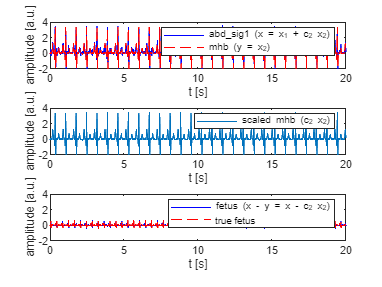


visualize_ecgs(t, abd_sig1, mhb, fetus, fhb, c2)

% Load problem3.mat to have access to variables abd_sig1 and mhb_ahead
load("problem3.mat")

% The sampling rates are 1000 Hz
FS = 1000;

% Calculate sample timing vector in seconds starting from 0
t = linspace(0, length(abd_sig1)/FS, length(abd_sig1))

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490



% Estimate the time lag using cross correlation with the 'xcorr' function
% Fit a spline to the cross correlation using 'spline' function, and then find the delay with maximum correlation using 'fnmin'
% NOTE: to use minimization function for maximization, please invert the objective function!
[r,lags] = xcorr(abd_sig1, mhb_ahead, 100)

r = 1.0e+04 *

    0.0204
    0.0204
    0.0206
    0.0210
    0.0218
    0.0228
    0.0241
    0.0257
    0.0276
    0.0298


lags =   -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51


pp = spline(lags, r)

pp = struct with fields:
      form: 'pp'
    breaks: [-100 -99 -98 -97 -96 -95 -94 -93 -92 -91 -90 -89 -88 -87 -86 -85 -84 -83 -82 -81 -80 -79 -78 -77 -76 -75 -74 -73 -72 -71 -70 -69 -68 -67 -66 -65 -64 -63 -62 -61 -60 -59 -58 -57 -56 -55 -54 -53 -52 -51 -50 -49 -48 -47 -46 -45 -44 -43 -42 … ]
     coefs: [200×4 double]
    pieces: 200
     order: 4
       dim: 1


[breaks,coefs,L,order,dim] = unmkpp(pp)

breaks =   -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51


coefs = 1.0e+04 *

    0.0000    0.0001   -0.0002    0.0204
    0.0000    0.0001    0.0001    0.0204
    0.0000    0.0001    0.0003    0.0206
   -0.0000    0.0002    0.0006    0.0210
    0.0000    0.0001    0.0009    0.0218
   -0.0000    0.0002    0.0011    0.0228
    0.0000    0.0001    0.0015    0.0241
    0.0000    0.0001    0.0017    0.0257
   -0.0000    0.0002    0.0021    0.0276
    0.0000    0.0001    0.0024    0.0298


L = 200

order = 4

dim = 1

pp2 = mkpp(breaks,-1*coefs,dim)

pp2 = struct with fields:
      form: 'pp'
    breaks: [-100 -99 -98 -97 -96 -95 -94 -93 -92 -91 -90 -89 -88 -87 -86 -85 -84 -83 -82 -81 -80 -79 -78 -77 -76 -75 -74 -73 -72 -71 -70 -69 -68 -67 -66 -65 -64 -63 -62 -61 -60 -59 -58 -57 -56 -55 -54 -53 -52 -51 -50 -49 -48 -47 -46 -45 -44 -43 -42 … ]
     coefs: [200×4 double]
    pieces: 200
     order: 4
       dim: 1


[minval,minsite] = fnmin(pp2)

minval = -1.0881e+04

minsite = 3.5535

d = minsite

d = 3.5535

% plot(r)

% Shift the chest ECG mhb_ahead back in time d samples
% Use linear interpolation with extrapolation with the function 'interp1'
mhb = interp1(t, mhb_ahead, t - d/FS, "linear", "extrap").'

mhb =    -0.0350
   -0.0350
   -0.0350
   -0.0350
   -0.0067
    0.0345
    0.0207
   -0.0226
   -0.0118
    0.0299



% Estimate c2 from abd_sig1 and mhb
c2 = mhb\abd_sig1

c2 = 1.0182


% Calculate the fetal ECG by cancelling out the scaled mother's ECG using projection based estimation coefficient
fetus = abd_sig1 - c2 * mhb

fetus =     0.0246
    0.0513
    0.0316
    0.0042
   -0.0150
    0.0097
   -0.0356
    0.0100
   -0.0375
    0.0382


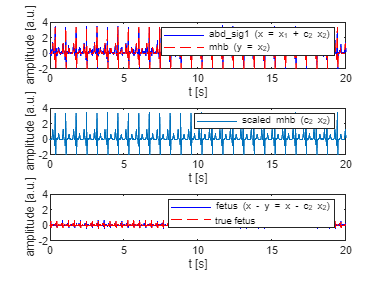


visualize_ecgs(t, abd_sig1, mhb, fetus, fhb, c2)

load('problem4.mat');

MU_MAX = 0.05;
FILTER_LENGHTS = [1 5 11 15 21 31 51 101]';
ADAPTATION_RATES = (0.1:0.1:1)';

[best_m, best_c, best_w, best_mse] = findBestFilterParameters(mhb_ahead_PI, abd_sig1, fhb, FILTER_LENGHTS, ADAPTATION_RATES, MU_MAX)

best_m = 31

best_c = 0.3000

best_w =     0.2063
    0.1675
    0.1294
    0.1094
    0.0858
    0.0523
    0.0425
    0.0358
    0.0348
    0.0373


best_mse = 0.0033